# EMT Basic Functionalities

## **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'net2-cl2.inp'; % you can also try 'net2-cl2.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded sucessfuly.


G =   epanet with properties:

                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
                              Errcode: 0
                            InputFile: 'C:\Users\eldemet\OneDr

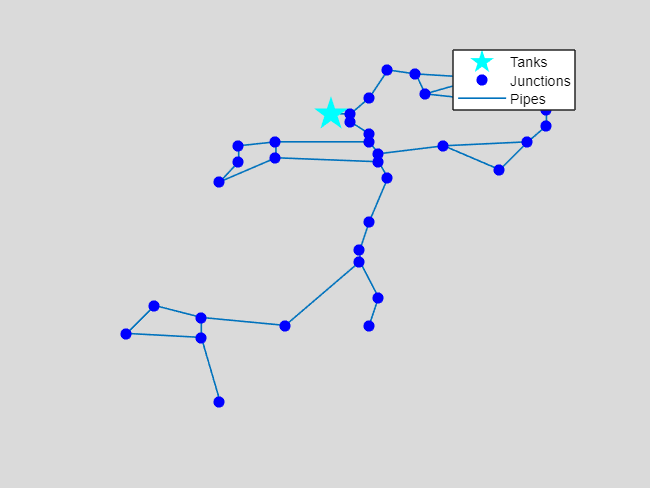

ans =   Axes with properties:

             XLim: [6.5000 60.5000]
             YLim: [-4.3000 95.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


G.plot

## **Running your first analysis**

There are 4 ways to run a simulation using the Toolkit

- Using the batch hydraulic/quality analysis function

- Using the iterative (step-by-step) hydraulic/quality analysis function

- Using the ENepanet function binary file

- Using the command line and the binary file

% set simulation duration at hours 
hrs = 48 

hrs = 48

G.setTimeSimulationDuration(3600*hrs)

Execute the simulation using the batch hydraulic analysis method

H = G.getComputedHydraulicTimeSeries 

H = struct with fields:
             Time: [49×1 double]
         Pressure: [49×36 double]
           Demand: [49×36 double]
    DemandDeficit: [49×36 double]
             Head: [49×36 double]
       TankVolume: [49×36 double]
             Flow: [49×40 double]
         Velocity: [49×40 double]
         HeadLoss: [49×40 double]
           Status: [49×40 double]
          Setting: [49×40 double]
           Energy: [49×40 double]
       Efficiency: [49×40 double]


Execute the simulation using the batch quality analysis method

Q = G.getComputedQualityTimeSeries

Q = struct with fields:
            Time: [49×1 double]
     NodeQuality: [49×36 double]
     LinkQuality: [49×40 double]
    MassFlowRate: [49×36 double]


## Other methods  to run EPANET

Method using the binary result file

Hbin = G.getBinComputedAllParameters 

Hbin = struct with fields:
         BinNumberReportingPeriods: 56
                    Binmagicnumber: 516114521
                      BinLibEPANET: 20012
                    BinNumberNodes: 36
          BinNumberReservoirsTanks: 1
                    BinNumberLinks: 40
                    BinNumberPumps: 0
                   BinNumberValves: 0
             BinWaterQualityOption: 1
         BinIndexNodeSourceTracing: 0
                BinFlowUnitsOption: 1
            BinPressureUnitsOption: 0
             BinTimeStatisticsFlag: 0
          BinReportingStartTimeSec: 0
           BinReportingTimeStepSec: 3600
          BinSimulationDurationSec: 198000
                  BinProblemTitle1: 'EPANET Example Network 2                                                        '
                  BinProblemTitle2: '                                                                                '
                  BinProblemTitle3: '                                                                   

Method using the EPANET executable

Hexe = G.getComputedTimeSeries

Hexe = struct with fields:
              Time: [49×1 double]
          Pressure: [49×36 double]
            Demand: [49×36 double]
              Head: [49×36 double]
       NodeQuality: [49×36 double]
              Flow: [49×40 double]
          Velocity: [49×40 double]
          HeadLoss: [49×40 double]
            Status: [49×40 double]
           Setting: [49×40 double]
      ReactionRate: [49×40 double]
    FrictionFactor: [49×40 double]
       LinkQuality: [49×40 double]


Method using the ENepanet library function (fastest)

Hbatch = G.getComputedTimeSeries_ENepanet

Hbatch = struct with fields:
              Time: [49×1 double]
          Pressure: [49×36 double]
            Demand: [49×36 double]
              Head: [49×36 double]
       NodeQuality: [49×36 double]
              Flow: [49×40 double]
          Velocity: [49×40 double]
          HeadLoss: [49×40 double]
            Status: [49×40 double]
           Setting: [49×40 double]
      ReactionRate: [49×40 double]
    FrictionFactor: [49×40 double]
       LinkQuality: [49×40 double]


## Plot results

% Get pressure in meters
P = H.Pressure

P =   112.6079   88.9211  105.9810  105.8004   88.4516   76.7385   59.6289   81.2932   50.6943   72.6267   48.0835   36.2105   35.9048   40.0956   44.3498   61.6915   48.6737   83.3359   61.6743   53.0837   61.7396   40.0747   26.8263   44.2904   26.7641   70.0854   78.7495   78.7496   70.0831   44.0926   79.0029   48.7403   44.4072   78.7496   78.7495   24.5681
  113.4491   89.7622  106.8269  106.6386   89.2884   77.5531   60.3875   82.0520   51.4415   73.3856   48.8066   36.8438   36.5065   40.6815   44.9204   62.2778   49.2546   83.9179   62.2576   53.6728   62.3317   40.6668   27.3277   44.8407   27.2407   70.5647   79.2293   79.2294   70.5630   44.5703   79.5849   49.3325   44.9995   79.2293   79.2293   25.0282
  114.1616   90.4747  107.5409  107.3502   89.9994   78.2571   61.0735   82.7381   52.1238   74.0717   49.4812   37.4891   37.1415   41.3111   45.5448   62.9082   49.8833   84.5468   62.8870   54.3034   62.9631   41.2982   27.9280   45.4582   27.8325   71.1572   79.8220   7

F = H.Flow

F =   666.6240  548.3642  108.1798   90.5398   80.4598  618.7440  612.4440   17.6400  589.7640    6.3000  572.1240  528.3012  508.1412  418.2689  355.2689   87.3523   15.9677   38.7569   29.5246    4.3246   23.3954   60.4800   18.3389   -1.8211   18.2011  322.9212  336.7812  312.8412  259.9212   45.3600   23.9400   13.8600    2.5734    3.7800    1.8900  -17.0954    2.4666    3.7800    1.3134    1.2600
  666.6240  551.1481  107.1559   92.5959   84.2759  627.1040  621.9040   14.5600  603.1840    5.2000  588.6240  552.4528  535.8128  442.9776  390.9776   90.7552   -5.4752   44.4408   18.1656   -2.6344   25.5144   49.9200   15.1369   -1.5031   15.0231  382.9328  394.3728  374.6128  330.9328   37.4400   19.7600   11.4400    1.7906    3.1200    1.5600  -20.3144    2.3694    3.1200    0.7506    1.0400
  666.6240  552.0385  106.8256   93.2456   85.4855  629.7640  624.9140   13.5800  607.4540    4.8500  593.8740  560.1374  544.6174  450.9524  402.4524   91.7250  -12.1850   46.1323   14.5472   -

C = Q.NodeQuality

C =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.1000
    0.8000    0.7568    0.6665    0.4134    0.7054    0.6860    0.4281    0.4768    0.4282    0.4718    0.4282    0.4285    0.4286    0.4288    0.4292    0.4209    0.4340    0.4697    0.4438    0.4580    0.4550    0.4515    0.4305    0.4296    0.4310    0.4493    0.4905    0.4543    0.4906    0.4628    0.4577    0.4905    0.4903    0.4905    0.4905    0.1049
    0.8000    0.7568    0.6819    0.6125    0.6942    0.6762    0.6325    0.4569    0.6319    0.4625    0.6187    0.5878    0.5819    0.5558    0.5112    0.3544    0.3594    0.4513    0.3927    0.4233    0.4185    0.4123    0.3777    0.4622    0.3750    0.4173    0.4817    


% Translate time to plots 
T = H.Time

T =            0
        3600
        7200
       10800
       14400
       18000
       21600
       25200
       28800
       32400


Tcl = Q.Time

Tcl =            0
        3600
        7200
       10800
       14400
       18000
       21600
       25200
       28800
       32400


TD = datetime(2022,7,18,0,0,T) % specify datetime structure

TD = 49×1 datetime array
   18-Jul-2022 00:00:00
   18-Jul-2022 01:00:00
   18-Jul-2022 02:00:00
   18-Jul-2022 03:00:00
   18-Jul-2022 04:00:00
   18-Jul-2022 05:00:00
   18-Jul-2022 06:00:00
   18-Jul-2022 07:00:00
   18-Jul-2022 08:00:00
   18-Jul-2022 09:00:00
   18-Jul-2022 10:00:00
   18-Jul-2022 11:00:00
   18-Jul-2022 12:00:00
   18-Jul-2022 13:00:00
   18-Jul-2022 14:00:00
   18-Jul-2022 15:00:00
   18-Jul-2022 16:00:00
   18-Jul-2022 17:00:00
   18-Jul-2022 18:00:00
   18-Jul-2022 19:00:00
   18-Jul-2022 20:00:00
   18-Jul-2022 21:00:00
   18-Jul-2022 22:00:00
   18-Jul-2022 23:00:00
   19-Jul-2022 00:00:00
   19-Jul-2022 01:00:00
   19-Jul-2022 02:00:00
   19-Jul-2022 03:00:00
   19-Jul-2022 04:00:00
   19-Jul-2022 05:00:00


TQ = datetime(2022,7,18,0,0,Tcl) % specify datetime structure

TQ = 49×1 datetime array
   18-Jul-2022 00:00:00
   18-Jul-2022 01:00:00
   18-Jul-2022 02:00:00
   18-Jul-2022 03:00:00
   18-Jul-2022 04:00:00
   18-Jul-2022 05:00:00
   18-Jul-2022 06:00:00
   18-Jul-2022 07:00:00
   18-Jul-2022 08:00:00
   18-Jul-2022 09:00:00
   18-Jul-2022 10:00:00
   18-Jul-2022 11:00:00
   18-Jul-2022 12:00:00
   18-Jul-2022 13:00:00
   18-Jul-2022 14:00:00
   18-Jul-2022 15:00:00
   18-Jul-2022 16:00:00
   18-Jul-2022 17:00:00
   18-Jul-2022 18:00:00
   18-Jul-2022 19:00:00
   18-Jul-2022 20:00:00
   18-Jul-2022 21:00:00
   18-Jul-2022 22:00:00
   18-Jul-2022 23:00:00
   19-Jul-2022 00:00:00
   19-Jul-2022 01:00:00
   19-Jul-2022 02:00:00
   19-Jul-2022 03:00:00
   19-Jul-2022 04:00:00
   19-Jul-2022 05:00:00


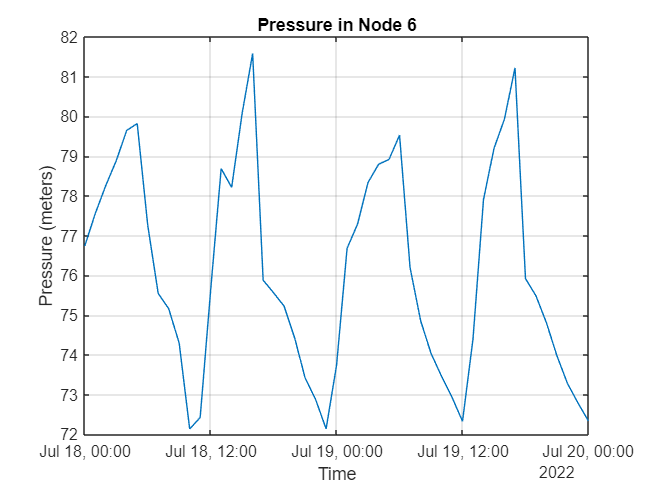


% Plot
figure
plot(TD,P(:,6))
grid on
title(['Pressure in Node ',G.getNodeNameID{6}])
ylabel('Pressure (meters)')
xlabel('Time')


pipeindex=G.getLinkIndex('1')

pipeindex = int32
1

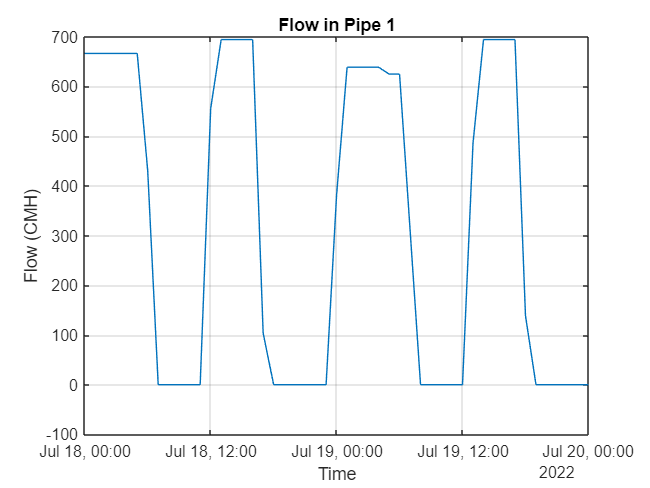

figure
plot(TD,F(:,pipeindex))
grid on
title(['Flow in Pipe ',G.getLinkNameID{pipeindex}])
ylabel('Flow (CMH)')
xlabel('Time')

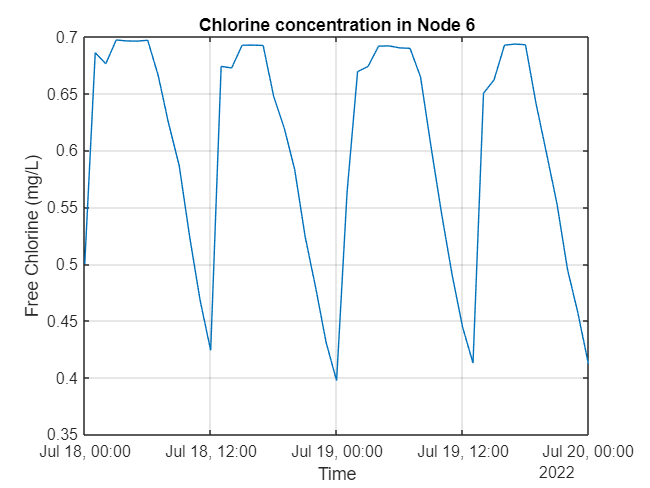


figure
plot(TQ,C(:,6))
grid on
title(['Chlorine concentration in Node ',G.getNodeNameID{6}])
ylabel('Free Chlorine (mg/L)')
xlabel('Time')



% Your turn: Plot Chlorine in node with index 10 




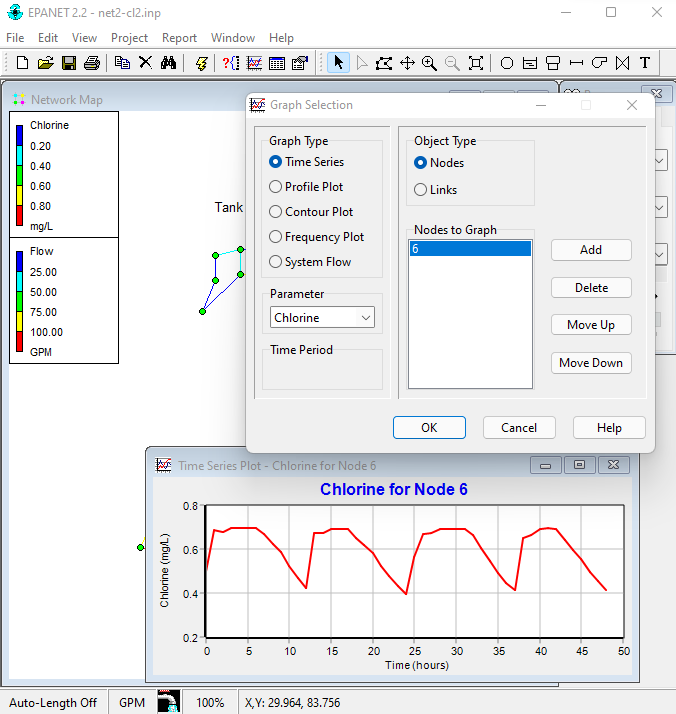

**Plot node pressures for specific nodes **

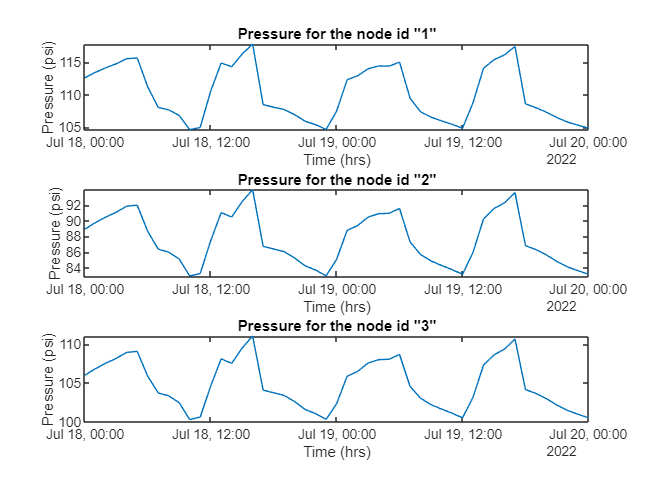

node_indices = [1, 2, 3];
node_names = G.getNodeNameID(node_indices);
figure;
for k=1:length(node_indices)
    subplot(3,1,k)    
    plot(TD, P(:,node_indices(k)));
    title(['Pressure for the node id "', G.getNodeNameID{node_indices(k)},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Pressure (', G.NodePressureUnits,')'])
end

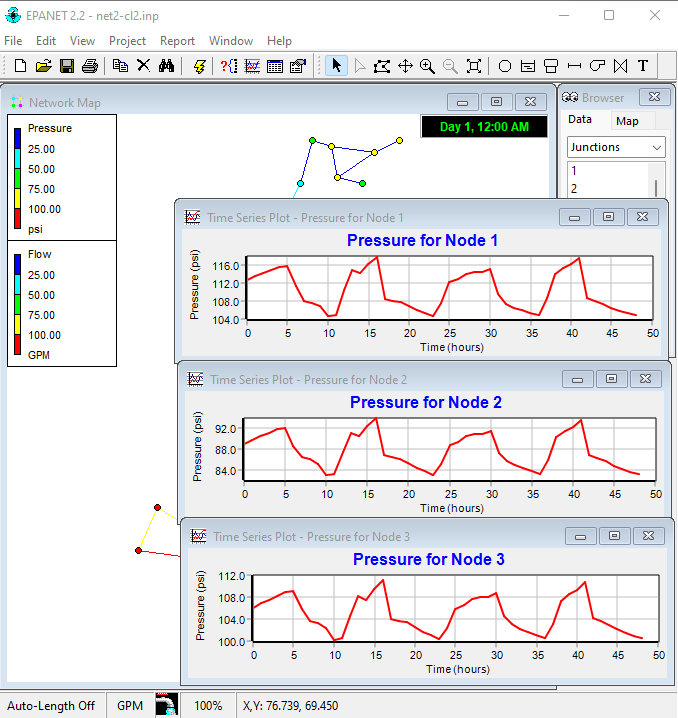

## Iteratively (step-by-step) hydraulic analysis

% 4 steps to run hydraulics
G.openHydraulicAnalysis; % Step 1
G.initializeHydraulicAnalysis; % Step 2

tstep=1;P2=[];T2=[];D2=[];H2=[];F2=[];

while (tstep>0)
    ttmp = G.runHydraulicAnalysis; % Step 3
    P2=[P2; G.getNodePressure];
    D2=[D2; G.getNodeActualDemand];
    H2=[H2; G.getNodeHydaulicHead];
    F2=[F2; G.getLinkFlows];
    T2=[T2; ttmp];
    tstep=G.nextHydraulicAnalysisStep; % Step 4
end

G.closeHydraulicAnalysis;

Plot figures

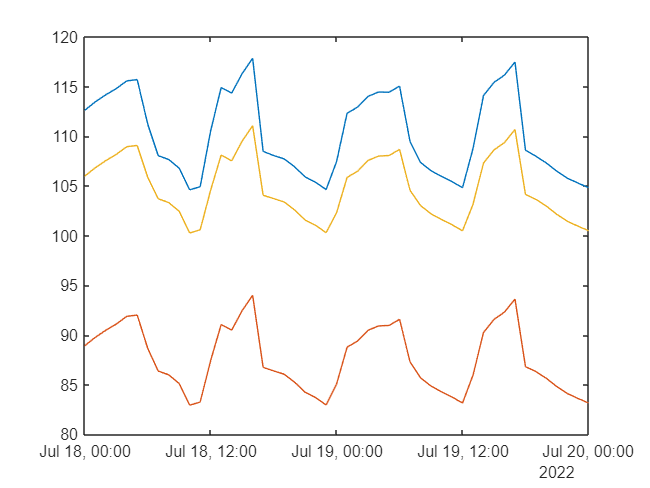

figure
plot(TD, P2(:, node_indices))

## Iteratively (step-by-step) quality analysis

% requires solveCompleteHydraulics
G.openQualityAnalysis
G.initializeQualityAnalysis
tleft=1; QT=[];QsN=[]; QsL=[]; 
while (tleft>0)
    ttmp=G.runQualityAnalysis;
    QsN=[QsN; G.getNodeActualQuality];
    QsL=[QsL; G.getLinkActualQuality];
    QT=[QT; ttmp];
    tleft = G.stepQualityAnalysisTimeLeft;
end
G.closeQualityAnalysis;

Plot figures

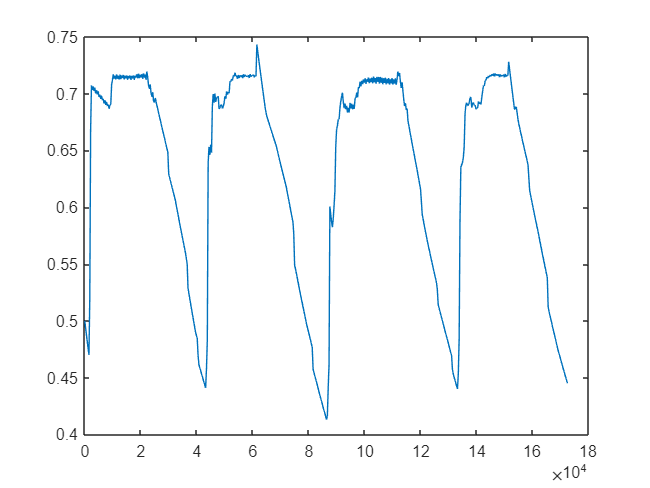

figure
plot(QT, QsN(:, 5))